# doppler calculation

this script is used for calculation of doppler shift and rate

## satellite params

clear;
satAltitude=550e3; %in meters
Fc=900e6;%carrier frequency
minElevAngle=0;

## sim

based on toolbox example code

%sat characteristics
semiMajorAxis = satAltitude+6371000;
eccentricity = 0;
inclination = 0; 
rightAscensionOfAscendingNode = 0; 
argumentOfPeriapsis = 0; 
trueAnomaly = 0; 

% Calculate orbital period
mu = 3.986e14; % Gravitational parameter of Earth (m^3/s^2) = G*M
orbitalPeriod = 2 * pi * sqrt((semiMajorAxis^3) / mu)

orbitalPeriod = 5.7301e+03


%generate time vector
startTime = datetime(2020,5,1,11,36,0);
stopTime = startTime + seconds(1*orbitalPeriod);
sampleTime=5;
timePoints = startTime:seconds(sampleTime):stopTime;

sc = satelliteScenario(startTime,stopTime,sampleTime);
lat = 0;
lon = 180;
minElevationAngle=minElevAngle;
gs = groundStation(sc,lat,lon,"MinElevationAngle",minElevationAngle);


sat = satellite(sc,semiMajorAxis,eccentricity,inclination, rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly);


names = sat.Name + " Camera";
cam = conicalSensor(sat,"Name",names,"MaxViewAngle",179.99);
pointAt(sat,gs);
ac = access(cam,gs);

fov = fieldOfView(cam);

%show(sat)

accessIntervals(ac)

ans = 1×8 table
           Source                 Target          IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ____________________    __________________    ______________    ____________________    ____________________    ________    __________    ________

    "Satellite 2 Camera"    "Ground station 1"          1           01-May-2020 12:30:15    01-May-2020 12:43:05      770           1            1    


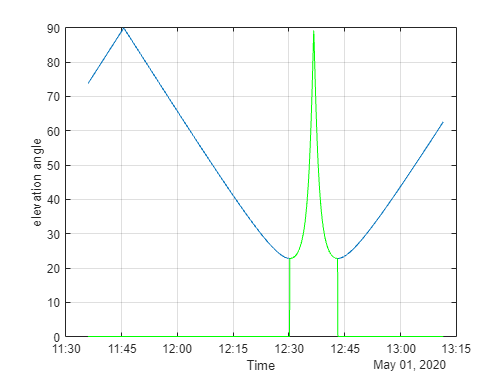

elevationRangeMatrix=0;
s = accessStatus(ac);
for i = 1:numel(timePoints)
    % Get elevation angle etc between satellite and ground station
    [azimuth,elevation,range] = aer(sat,gs,startTime+seconds((i-1)*sampleTime));
    elevationRangeMatrix(i,1)=elevation;%elevation an
    elevationRangeMatrix(i,2)=range;
    elevationRangeMatrix(i,3)=((i-1)*sampleTime);
    
    % if(s(i)==1)
    % 
    %     counter=counter+1;
    % else
    %     elevationRangeMatrix(i,1)=0;
    %     elevationRangeMatrix(i,2)=0;
    %     elevationRangeMatrix(i,3)=((i-1)*sampleTime);
    % end
end
elevationRangeMatrix(:,4)=s(1:numel(s)-1);%1 if accesStatus is true

hold off
plot(timePoints,-1*elevationRangeMatrix(:,1))
hold on
plot(timePoints,-1*elevationRangeMatrix(:,1).*elevationRangeMatrix(:,4),"green")
grid on
ylim([0 90])
xlabel("Time");
ylabel("elevation angle");
hold off


el_min=min(-1*elevationRangeMatrix(:,1))

el_min = 22.7821

el_max=max(-1*elevationRangeMatrix(:,1))

el_max = 89.9573

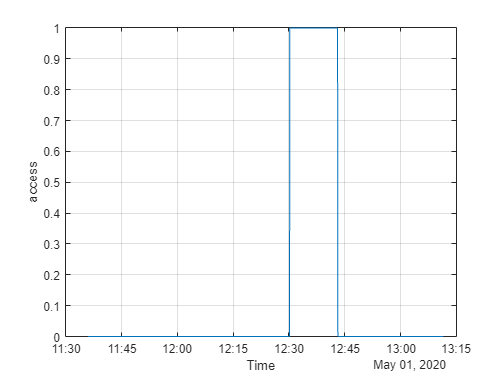



plot(timePoints,elevationRangeMatrix(:,4))
grid on
xlabel("Time");
ylabel("access");

hold off

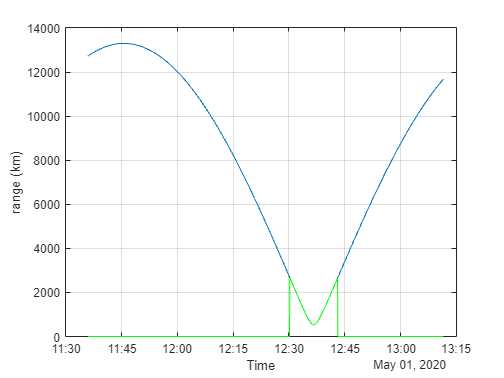

plot(timePoints,elevationRangeMatrix(:,2)/1000)
hold on
plot(timePoints,elevationRangeMatrix(:,2)/1000.*elevationRangeMatrix(:,4),"green")
grid on;
xlabel("Time");
ylabel("range (km)");
hold off


range_min=min(elevationRangeMatrix(:,2))

range_min = 5.3975e+05

range_max=max(elevationRangeMatrix(:,2))

range_max = 1.3296e+07

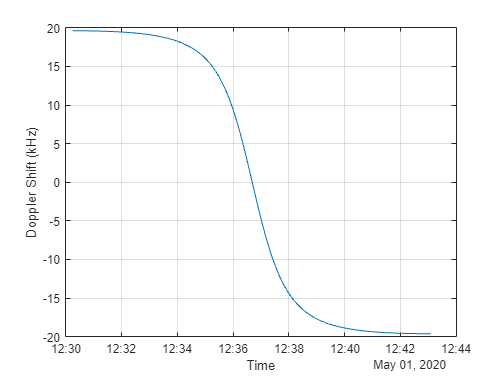


% Emitted carrier frequency in Hz
fc = Fc;
% Calculate Doppler shift and get additional information about Doppler. The
% Doppler information output contains relative velocity and Doppler rate.
% The dopplershift function internally performs access analysis and returns
% NaN whenever there is no access.
figure;
[fShift,time,dopplerInfo] = dopplershift(sat,gs,Frequency=fc);
plot(time,fShift(1,:)/1e3)                        % Plot in kHz
xlabel("Time")
ylabel("Doppler Shift (kHz)")
grid on

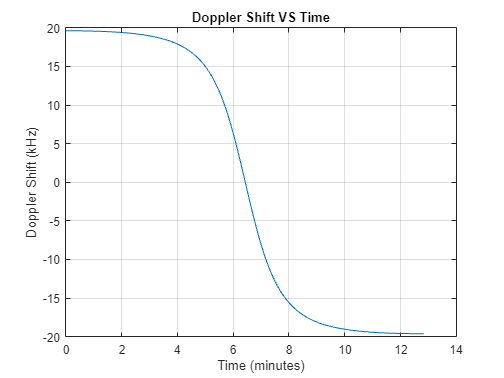



% Find indices where data is not NaN
validIndices = find(~isnan(fShift));

% Extract the relevant section of the data
relevantDshift = fShift(min(validIndices):max(validIndices));
relevantDrate = dopplerInfo.DopplerRate(min(validIndices):max(validIndices));
relevantTime= time(min(validIndices):max(validIndices));
% Convert the datetime vector to minutes from the start
timeInMinutes = minutes(relevantTime - relevantTime(1));

% Plot the relevant data
figure;
plot(timeInMinutes,relevantDshift(1,:)/1e3) 
grid on
xlabel('Time (minutes)');
ylabel('Doppler Shift (kHz)');
title('Doppler Shift VS Time');




maxDopplerShift = max(transpose(relevantDshift))

maxDopplerShift = 1.9629e+04

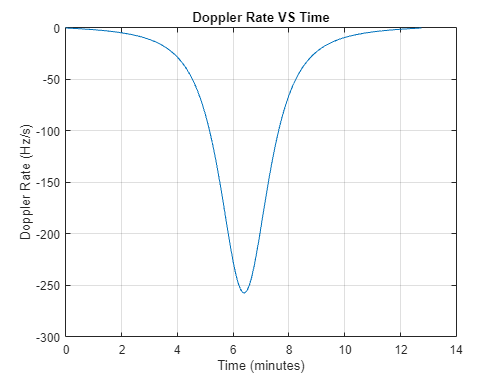


figure;
plot(timeInMinutes,relevantDrate(1,:)) 
grid on
xlabel('Time (minutes)');
ylabel('Doppler Rate (Hz/s)');
title('Doppler Rate VS Time');


sum(abs(relevantDrate(1,:))<150)/length(relevantDrate)

ans = 0.8581

maxDopplerRate=min(transpose(relevantDrate))

maxDopplerRate = -257.6727



% [azimuth1,elevation1,range1] = aer(sat,gs,datetime(2020,5,1,11,45,0))
% [azimuth2,elevation2,range2] = aer(sat,gs,datetime(2020,5,1,12,38,0))


## symbol times

for SF=7:12
    loraFs=125e3;
    loraSPS(SF-6)=2^SF;
    loraSymbolDuration(SF-6)=loraSPS(SF-6)/loraFs;
    bitrate(SF-6)=SF/loraSymbolDuration(SF-6);

    %maxDrateLora(SF-6)=(0.5*loraFs/(2^SF))/loraSymbolDuration(SF-6);%loraSymbolDuration
    maxDrateLora(SF-6)=(loraFs/(2^SF))/loraSymbolDuration(SF-6);%loraSymbolDuration

end
disp(loraSymbolDuration)

    0.0010    0.0020    0.0041    0.0082    0.0164    0.0328



disp(maxDrateLora)

   1.0e+05 *

    9.5367    2.3842    0.5960    0.1490    0.0373    0.0093



disp(bitrate)

   1.0e+03 *

    6.8359    3.9062    2.1973    1.2207    0.6714    0.3662




nbiotFs=180e3;
numSC=12;
cpLen=3;
nbiotSPS=(numSC+cpLen)/nbiotFs

nbiotSPS = 8.3333e-05